# Testing the aberrations compensation on dots


addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\addition\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\functions\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab\HelpFun\','-end')

**Set the constances and generate polinomials**

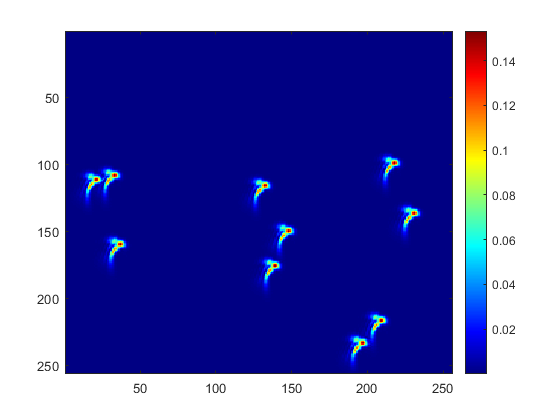

N = 256;
Global_constants = zeros(10,1);
lam = 0.85*10^-3; Global_constants(1)=lam; %Длина волны
k = 2*pi/(lam); Global_constants(2)=k; % Wave number in invers millimeters
dx = 300/256*10^-3; Global_constants(4)=dx; % it is pixel size in mm
L = dx*N; Global_constants(5)=L; % Length of image area

[x,y] = meshgrid(-L/2:dx:L/2-dx);
x = x + dx/2 ; % Это нужно, чтобы отцентрировать is_in_circle
y = y + dx/2;
kz = rphase3(dx,L,k);

radius = 0.14;
% This radius is determinated empirically. noise_area is area over which
% the noise is calculated
is_in_circle = circ(sqrt(x.^2+y.^2)/radius);
noise_area = circ(sqrt(x.^2+y.^2)/0.11) & ~circ(sqrt(x.^2+y.^2)/0.09);

Global_constants(10) = radius;
Global_constants(6) = 127; %xc
Global_constants(7) = 127; %yc

% tempz is used for sub-images that should not intersect with image borders
tempz = false(N,N);
tempz(12:244,12:244) = true;
clear Sh0;

fieldsprep; %This file contains references on different data with comments
figure(); imagesc(abs(E) ); colorbar; colormap(jet);

Eideal = Eideal.*normf(Eideal,E);

## Checking the efficienty of Winner filtering.

Select the one scaterrer

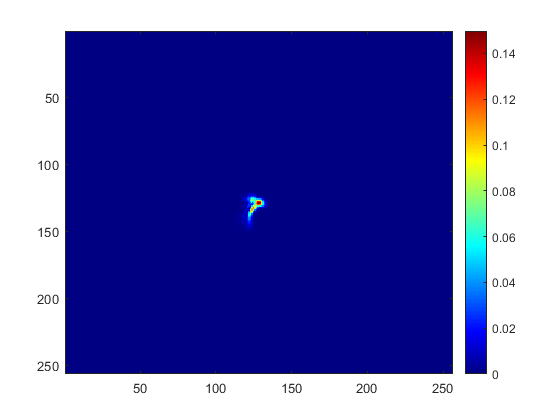

E2_1 = zeros(size(E));
E2_1(129-16:129+20,129-16:129+15) = E(116-16:116+20,133-16:133+15);
figure();
imagesc(abs(E2_1)); colormap(jet); colorbar;

#### Calculating ATF and inverse ATF (DC) by one scaterrer

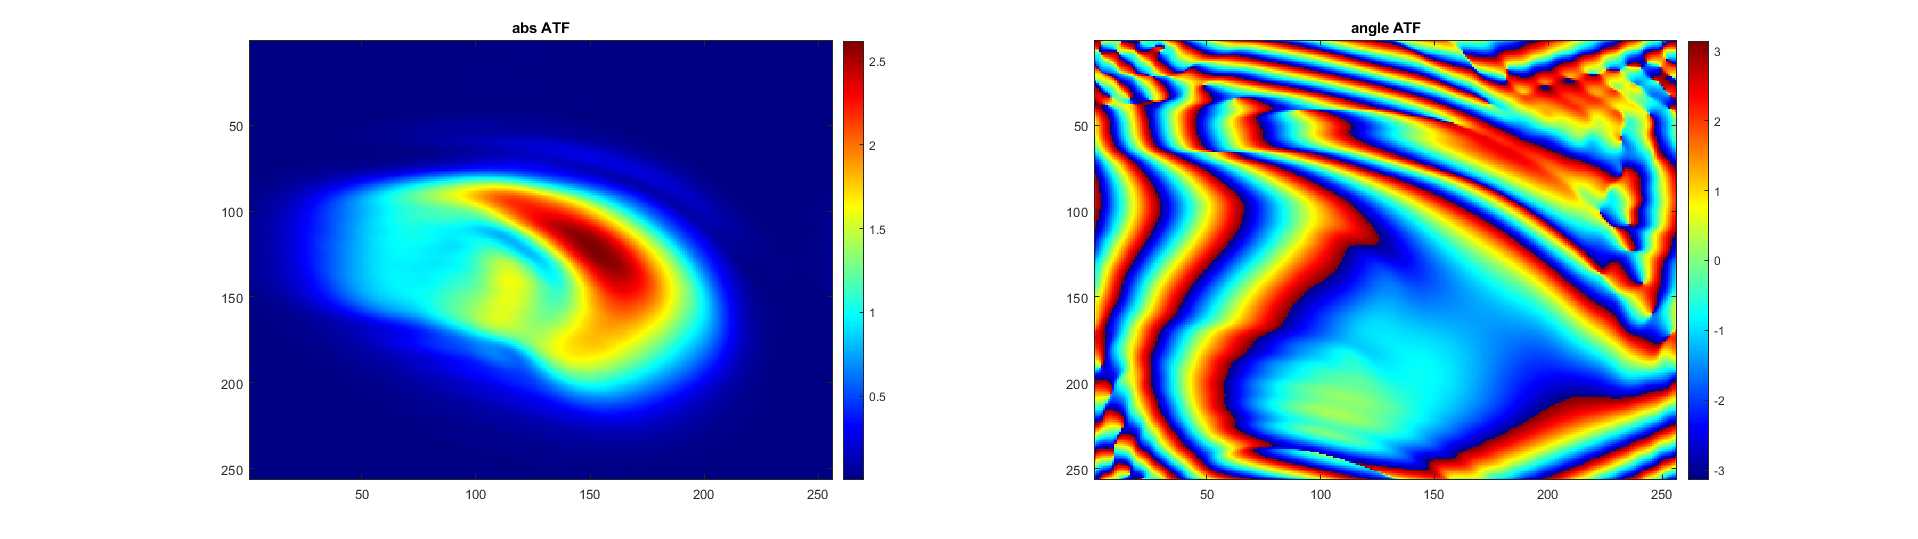

ATF = FTS(E2_1);

h11 = figure();
subplot(1,2,1);
imagesc(abs(ATF)); colormap(jet); colorbar();
title('abs ATF')
subplot(1,2,2);    
imagesc(angle(ATF)); colormap(jet); colorbar();
title('angle ATF')
set(h11,'Units','normalized','position',[0 0 1 .5])

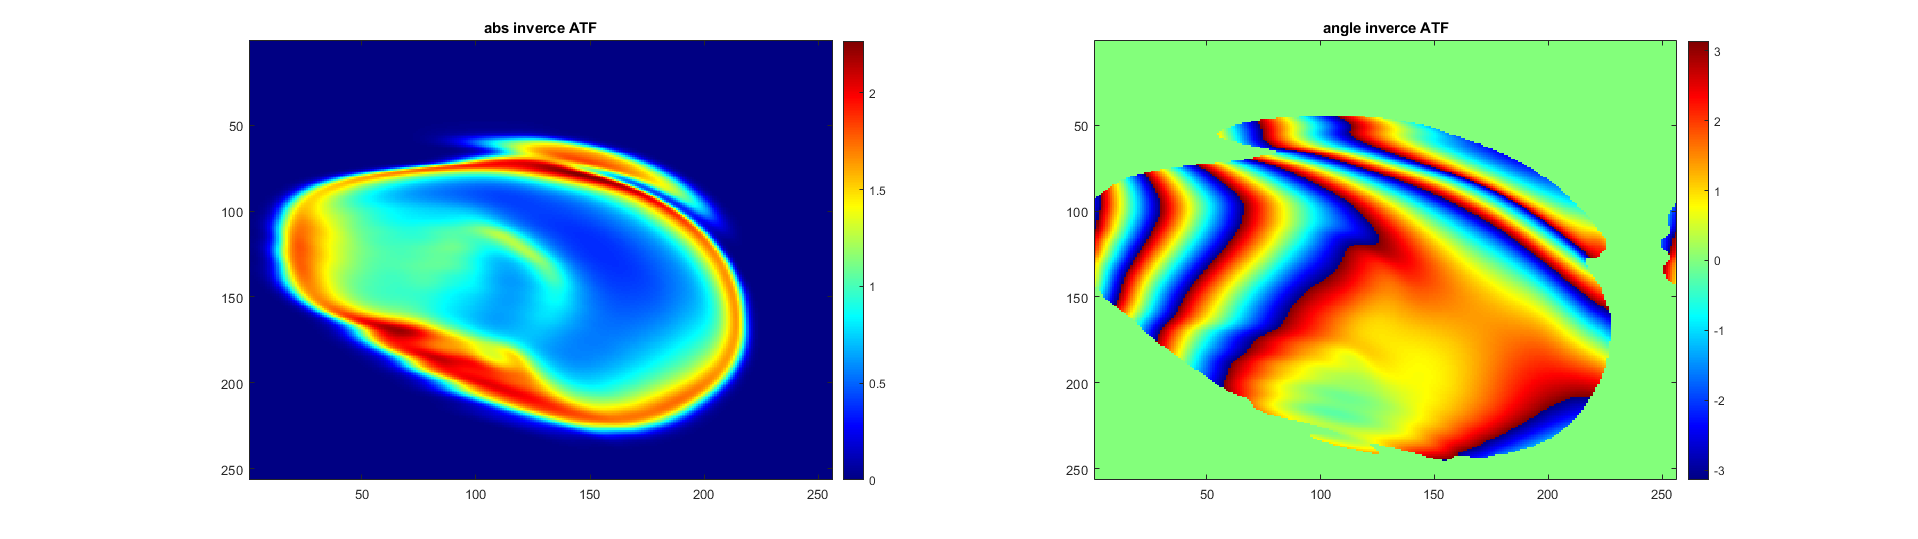

noise = mean( abs(ATF(noise_area)) )/10;

afImg = imgaussfilt(abs(ATF),1);
SNR = (afImg-noise)./noise;

filtr = (1./(1 + 1./( SNR ) ) );
tmp_filter2 = filtr < max(filtr(:))/29;

tmp_filter = tmp_filter2; 
aATF = abs(ATF);
H2 = aATF.^2;

Dc1 = (1./ATF).*(1./(1 + 1./( H2.*SNR.^2 ) ) );
Dc1(tmp_filter) = 0;
Dc1(isnan(Dc1)) = 0;

tmp_filter1 = aATF < max(aATF(:))/exp(3);
Dc1 = Dc1.*imgaussfilt(double(~tmp_filter1),25);


h13 = figure();
subplot(1,2,1);
imagesc(abs(Dc1)); colormap(jet); colorbar();
title('abs inverce ATF')
subplot(1,2,2);    
imagesc(angle(Dc1)); colormap(jet); colorbar();
title('angle inverce ATF')
set(h13,'Units','normalized','position',[0 0 1 .5])

#### Testing the efficiency of abs ATF compensation

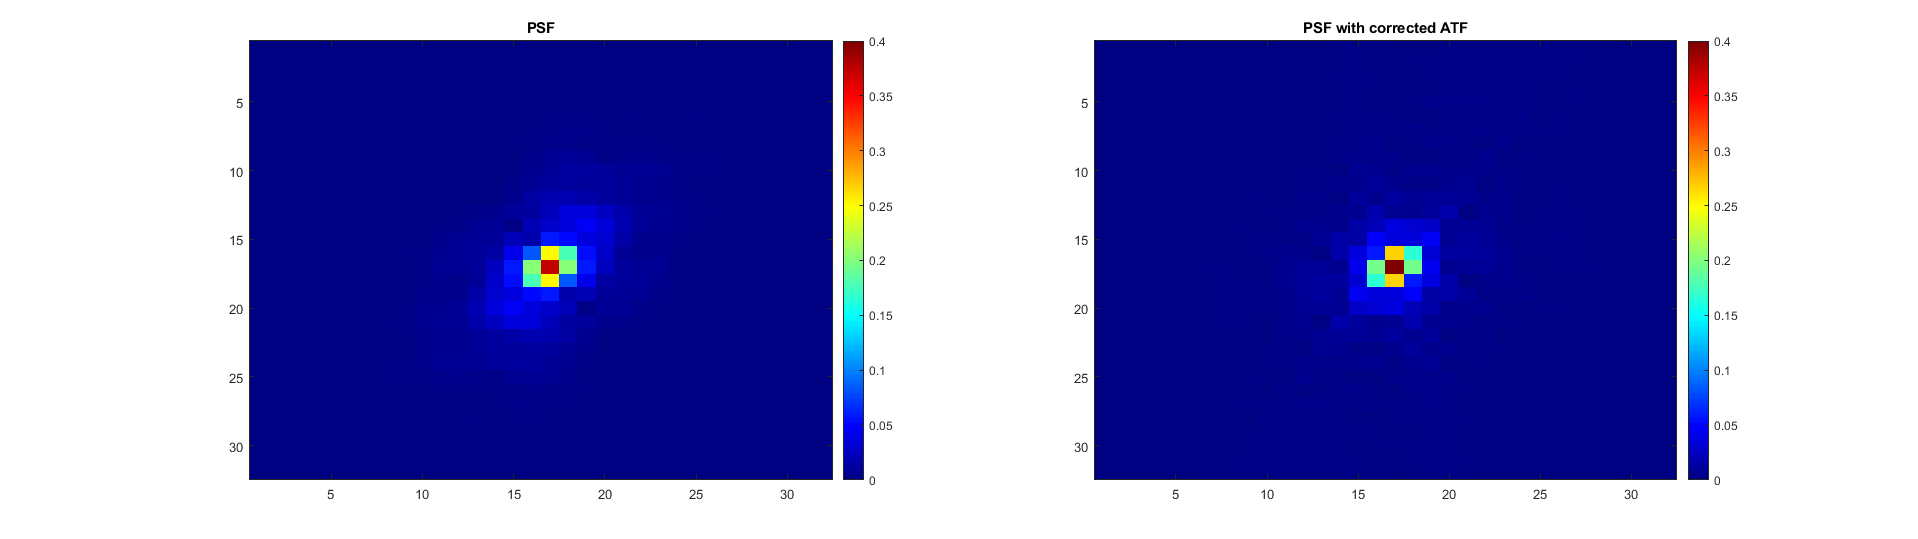

tmp1 = abs(FTS(aATF))/N.^2;
tmp2 = abs(FTS(aATF.*abs(Dc1)))/N.^2;

tmp2 = tmp2.*normf(tmp2,tmp1);

h131 = figure();
subplot(1,2,1);
imagesc(tmp1(129-16:129+15,129-16:129+15)); colormap(jet); colorbar(); caxis([0 .4]);
title('PSF')
subplot(1,2,2);    
imagesc(tmp2(129-16:129+15,129-16:129+15)); colormap(jet); colorbar(); caxis([0 .4]);
title('PSF with corrected ATF')
set(h131,'Units','normalized','position',[0 0 1 .5])

Shannon entropy of images without and with abs ATF correction coorespondely

sh1 = shann_entropy(tmp1(129-16:129+15,129-16:129+15));
sh2 = shann_entropy(tmp2(129-16:129+15,129-16:129+15));
[sh1,sh2]

ans =     3.7765    3.2603


clear tmp1 tmp2 sh1 sh2 

## Obtaining corrected image

#### Testing image correction with known PSF

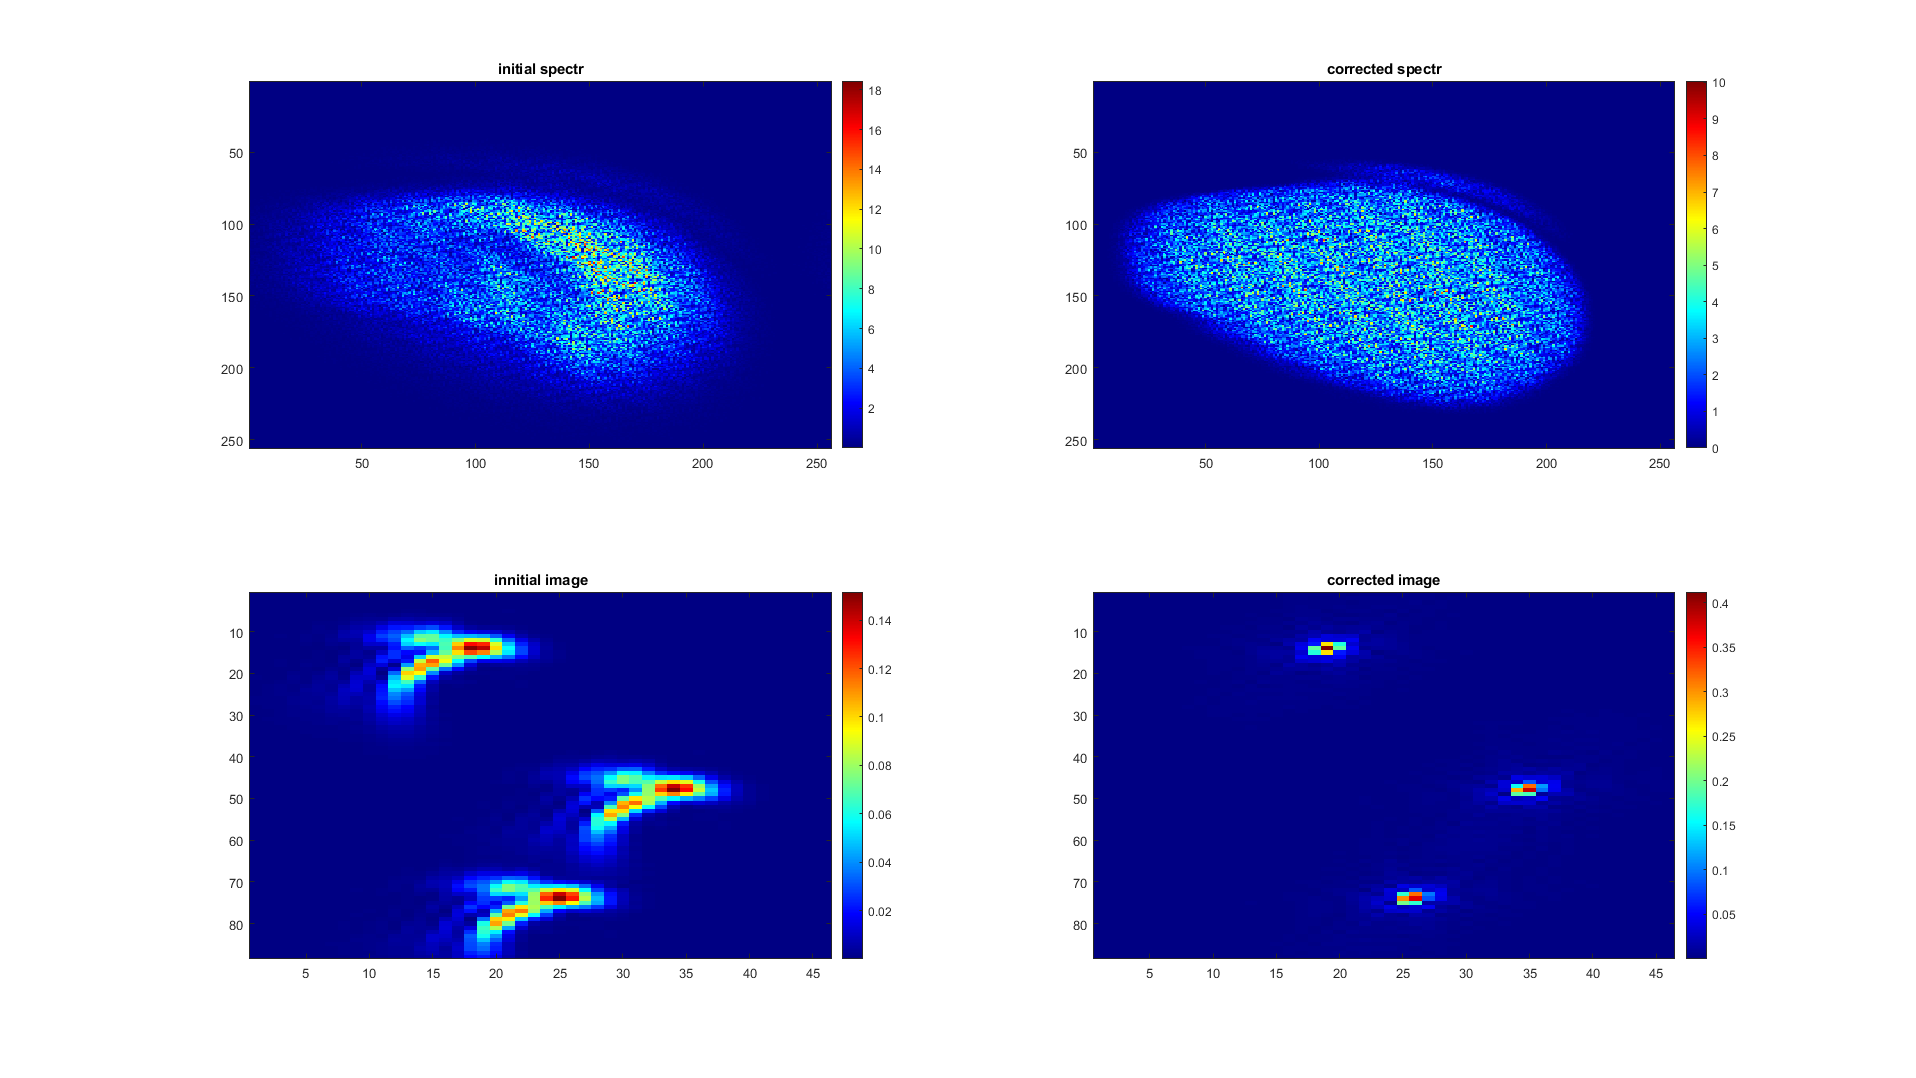

fE = FTS(E);
fE2 = fE.*Dc1;
E2cor = iFTS(fE2); 
E2cor = E2cor.*normf(E2cor,E);

h14 = figure();
subplot(2,2,1);
imagesc(abs(fE)); colormap(jet); colorbar();
title('initial spectr')
subplot(2,2,2);    
imagesc(abs(fE2)); colormap(jet); colorbar();
title('corrected spectr')
subplot(2,2,3);
imagesc(abs(E(103:190,115:160))); colormap(jet); colorbar();
title('innitial image')
subplot(2,2,4);    
imagesc(abs(E2cor(103:190,115:160))); colormap(jet); colorbar();
title('corrected image')
set(h14,'Units','normalized','position',[0 0 1 1])

sh1 = shann_entropy(E(103:190,115:160));
sh2 = shann_entropy(E2cor(103:190,115:160));
[sh1,sh2]

ans =     7.9504    4.8469


#### Testing abs and angle correction separately

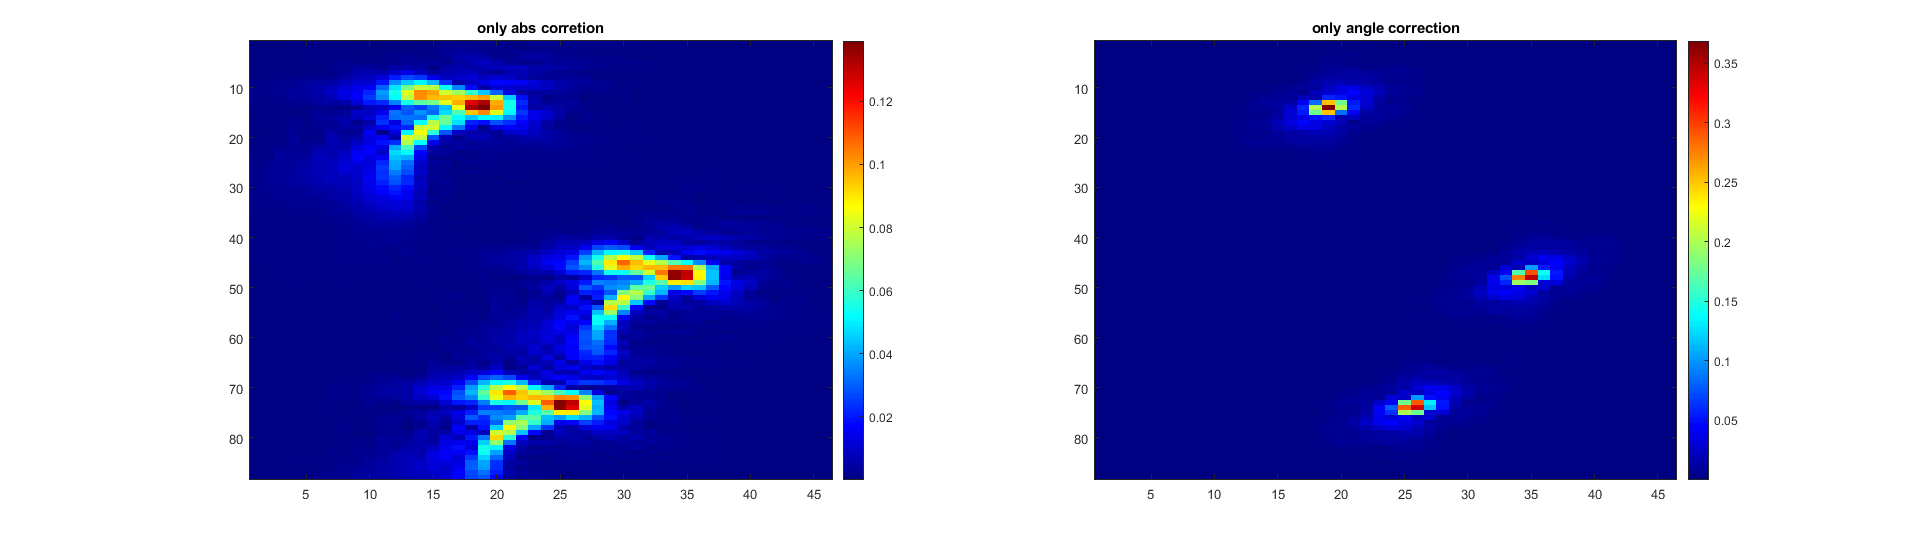

fE2_only_abs = fE.*abs(Dc1);
fE2_only_angle = fE.*exp(1j*angle(Dc1));

E2cor_only_abs    = iFTS(fE2_only_abs);
E2corr_only_angle = iFTS(fE2_only_angle);

E2cor_only_abs   = E2cor_only_abs.*normf(E2cor_only_abs,E);
E2corr_only_angle = E2corr_only_angle.*normf(E2corr_only_angle,E);

h15 = figure();
subplot(1,2,1);
imagesc(abs(E2cor_only_abs(103:190,115:160))); colormap(jet); colorbar();
title('only abs corretion')
subplot(1,2,2);    
imagesc(abs(E2corr_only_angle(103:190,115:160))); colormap(jet); colorbar();
title('only angle correction')
set(h15,'Units','normalized','position',[0 0 1 .5])

## Compensation with Gauss-Hermite polynomials.

**Generating the polynomials**

her_R = w is evaluated from the condition: $2^n x^n \exp \left(-\frac{x^2 }{w^2 }\right)=1$, there x = dx2t*64/2


Generate_HermPol = true; %Calculate Gauss-Hermite polynomials?
her_N = 12;    % The degree of Herm. pol.
her_R = 0.04; % The radius of Herm. pol.
dx2t = dx*N/64;
if Generate_HermPol == true
    [x2,y2] = meshgrid(-L/2:dx2t:L/2-dx2t);
    x2 = x2 + dx/2; % Это нужно, чтобы отцентрировать is_in_circle
    y2 = y2 + dx/2;
    H256 = HermitePol(x,y,her_N,her_R);
    H64 = HermitePol(x2,y2,her_N,her_R);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


Visualization first 36 polynomials

h1 = figure();

Tmp = zeros(64,64);

h = zeros(size(H64,2),1);

set(h1,'Units','normalized','position',[0 0 9 round(her_N^2/9+1)])

for i = 1:her_N

    for j = 1:her_N

        h = h*0;

        h((i-1)*her_N+j) = 1;

        Tmp(:) = H64*h;

        subplot(round(her_N^2/9+1),9,(i-1)*her_N+j);

        imagesc(Tmp); colormap(jet); colorbar();

    end

end

#### Testing decomposition of complex function by Gauss-Hermite polynomials.

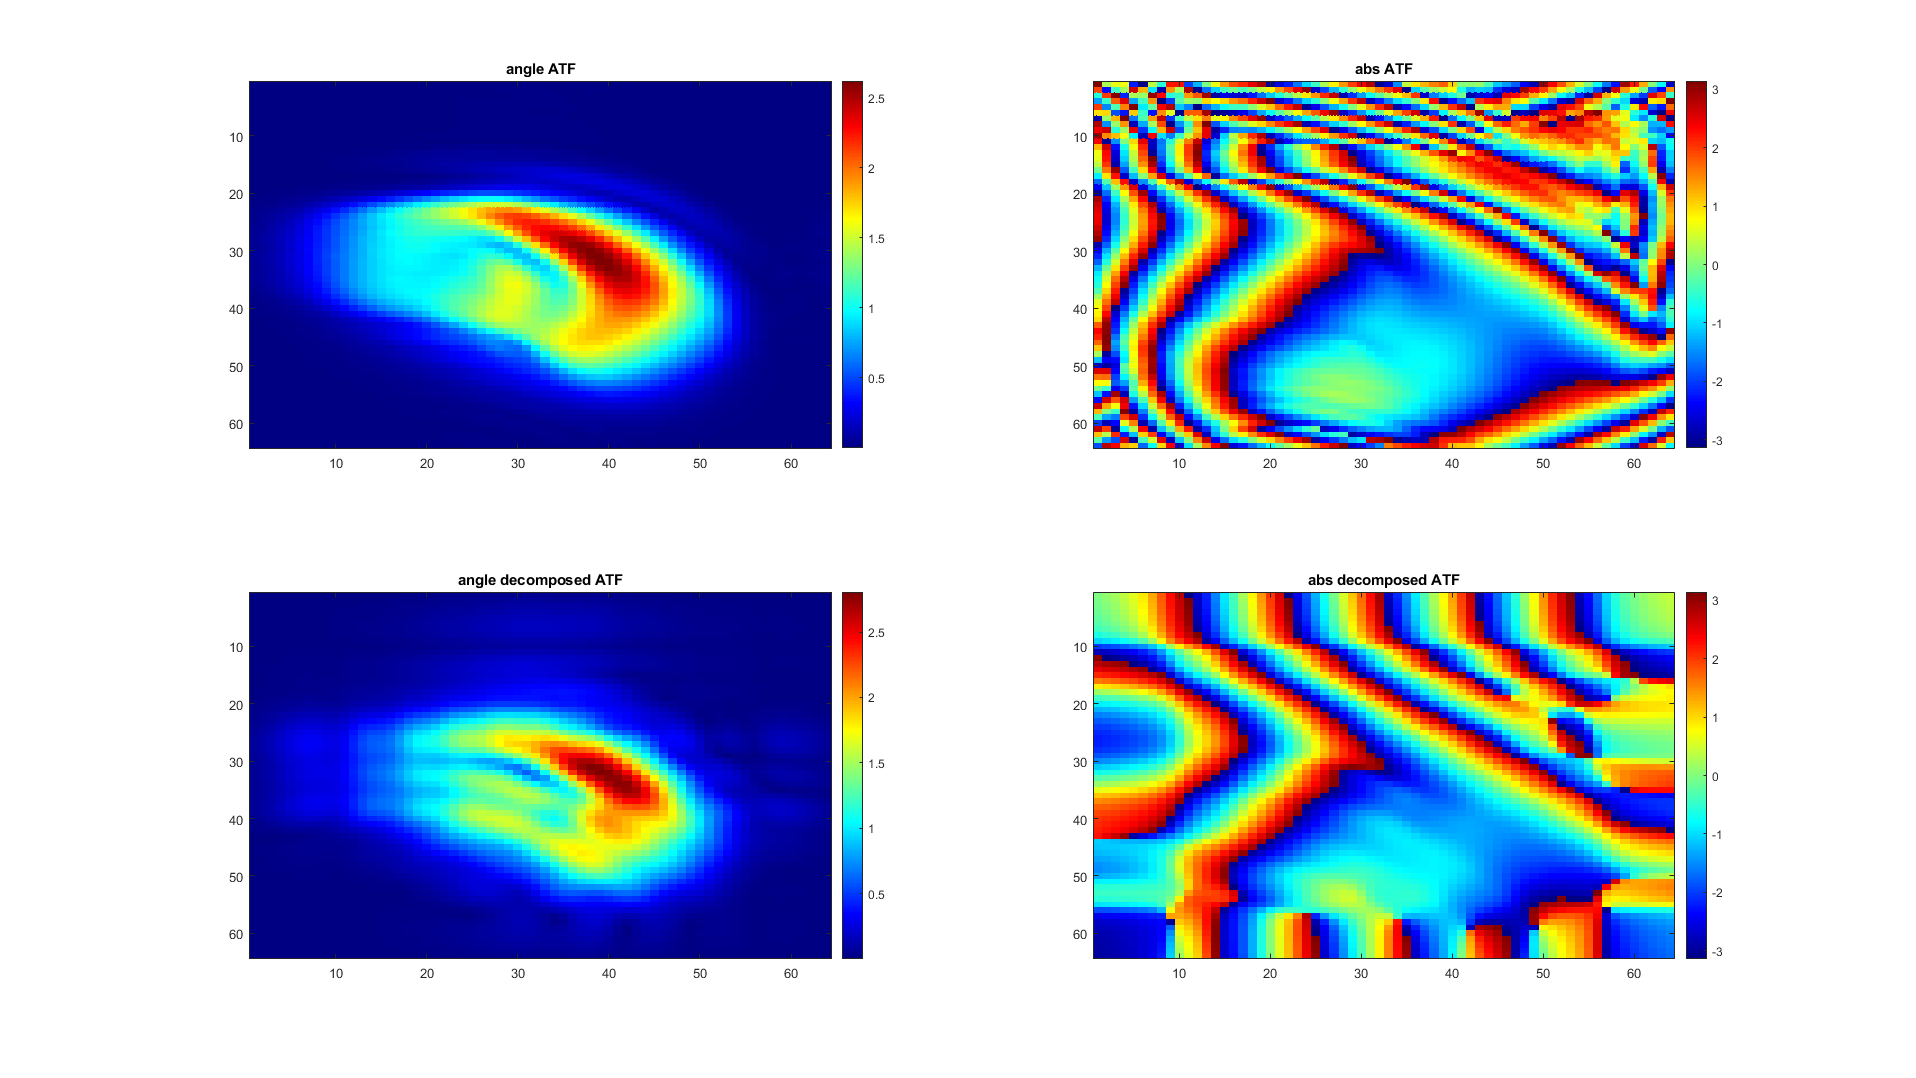

E2_2 = zeros(64,64);
E2_2(33-16:33+20,33-16:33+20) = E(116-16:116+20,133-16:133+20);
ATF = FTS(E2_2);

dxt = 300/256*10^-3;
Lt = dxt*256;
[x1,y1] = meshgrid(-Lt/2:dxt:Lt/2-dxt);
clear dxt;

ht = H64\ATF(:);
aATF2_64 = ATF*0;
aATF2_64(:) = H64*ht;

h15 = figure();
subplot(2,2,1);
imagesc(abs(ATF)); colormap(jet); colorbar();
title('angle ATF')
subplot(2,2,2);    
imagesc(angle(ATF)); colormap(jet); colorbar();
title('abs ATF')
subplot(2,2,3);
imagesc(abs(aATF2_64)); colormap(jet); colorbar();
title('angle decomposed ATF')
subplot(2,2,4);    
imagesc(angle(aATF2_64)); colormap(jet); colorbar();
title('abs decomposed ATF')

set(h15,'Units','normalized','position',[0 0 1 1])

#### Comparison of image quality between compensation with and without decomposition by polynomials

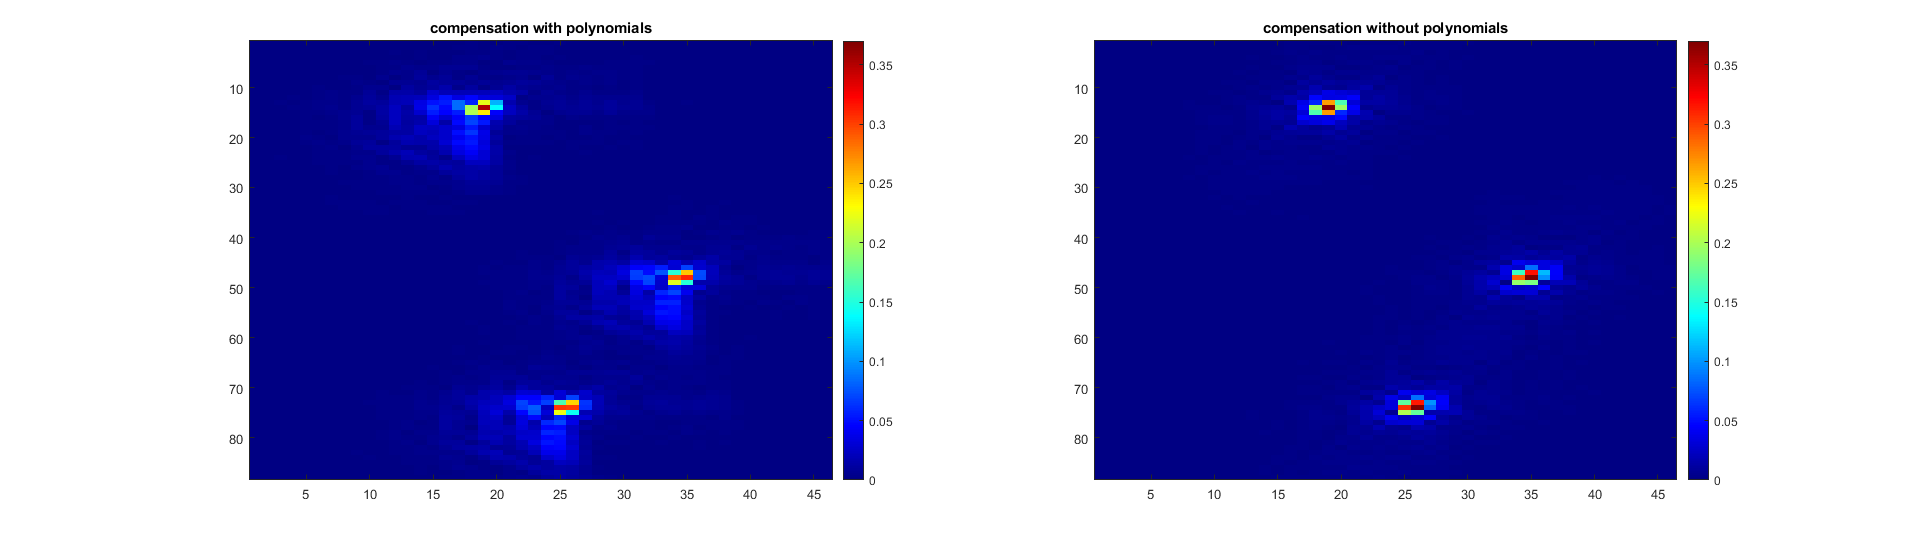

ATF256 = zeros(N,N);
ATF256(:) = H256*ht;

[Dc2] = WinF(ATF256,E,noise_area);

fE = FTS(E);
fE2_1 = fE.*Dc2; 
E2cor_1 = iFTS(fE2_1);

E2cor_1 = E2cor_1.*normf(E2cor_1,E); 

% imagesc(abs(E2cor_1(103:190,115:160))); colormap(jet); colorbar();
h16 = figure();
subplot(1,2,1);
imagesc(abs(E2cor_1(103:190,115:160))); colormap(jet); colorbar(); caxis([0 0.37]);
title('compensation with polynomials')
subplot(1,2,2);    
imagesc(abs(E2cor(103:190,115:160))); colormap(jet); colorbar(); caxis([0 0.37]);
title('compensation without polynomials')
set(h16,'Units','normalized','position',[0 0 1 .5])

shann_entropy(E2cor_1(103:190,115:160))

ans = 6.2093

**Anfortunately, amplitude compensation leads to little bit degradation of image -(**

## Compensation with Gausse-Hermite and Zernike polynomials

At first generates polynomials with lower degree

Generate_HermPol = true; %Calculate Gauss-Hermite polynomials?
her_N = 6;    % The degree of Herm. pol.
her_R = 0.057; % The radius of Herm. pol.
dx2t = dx*N/64;
if Generate_HermPol == true
    [x2,y2] = meshgrid(-L/2:dx2t:L/2-dx2t);
    x2 = x2 + dx2t/2; % Это нужно, чтобы отцентрировать is_in_circle
    y2 = y2 + dx2t/2;
    H256 = HermitePol(x,y,her_N,her_R);
    H64 = HermitePol(x2,y2,her_N,her_R);
end

I tested the decomposition of the full grid ATF and compared it with the 64x64 grid ATF. Work quality is approximately the same

% ATF = FTS(E2_1);
% aATF = abs(ATF);
% 
% ht = H256\aATF(:);

% % tmp_filter1 = aATF2 < max(aATF2(:))/exp(3);
% 
% %Zernike phase fitting
% [Z1,~,is_in1] = zerfit(ATF*0,x,y,0.14,8);
% 
% [ a2 ] = grad_svd( angle(ATF), N, Z1, is_in1);
% 
% aATF2 = aATF*0;
% aATF2(:) = H256*ht;
% 
% ATF(aATF < max(aATF2_64(:))/exp(3.5)) = 0;
% 
% Phase = zeros(size(ATF));
% a2(1:3) = 0;
% Phase(is_in1) = Z1*a2;
% 
% %         Phase(aATF2 < max(aATF2(:))/exp(3.5)) = 0;
% 
% ATF2 = aATF.*exp(1i*Phase);
% 
% noise = mean( abs(ATF2(noise_area)) )/10;
% 
% afImg = imgaussfilt(abs(ATF2),1);
% SNR = (afImg-noise)./noise;
% 
% filtr = (1./(1 + 1./( SNR ) ) );
% tmp_filter2 = filtr < max(filtr(:))/29;
% 
% tmp_filter = tmp_filter2; 
% aATF = abs(ATF2);
% H2 = aATF.^2;
% 
% Dc1 = (1./ATF).*(1./(1 + 1./( H2.*SNR.^2 ) ) );
% Dc1(tmp_filter) = 0;
% Dc1(isnan(Dc1)) = 0;
% 
% tmp_filter1 = aATF < max(aATF(:))/exp(3);
% Dc2 = Dc2.*imgaussfilt(double(~tmp_filter1),25);
% % clear ht tmp_filter1 Z1 is_in1 a2 aATF

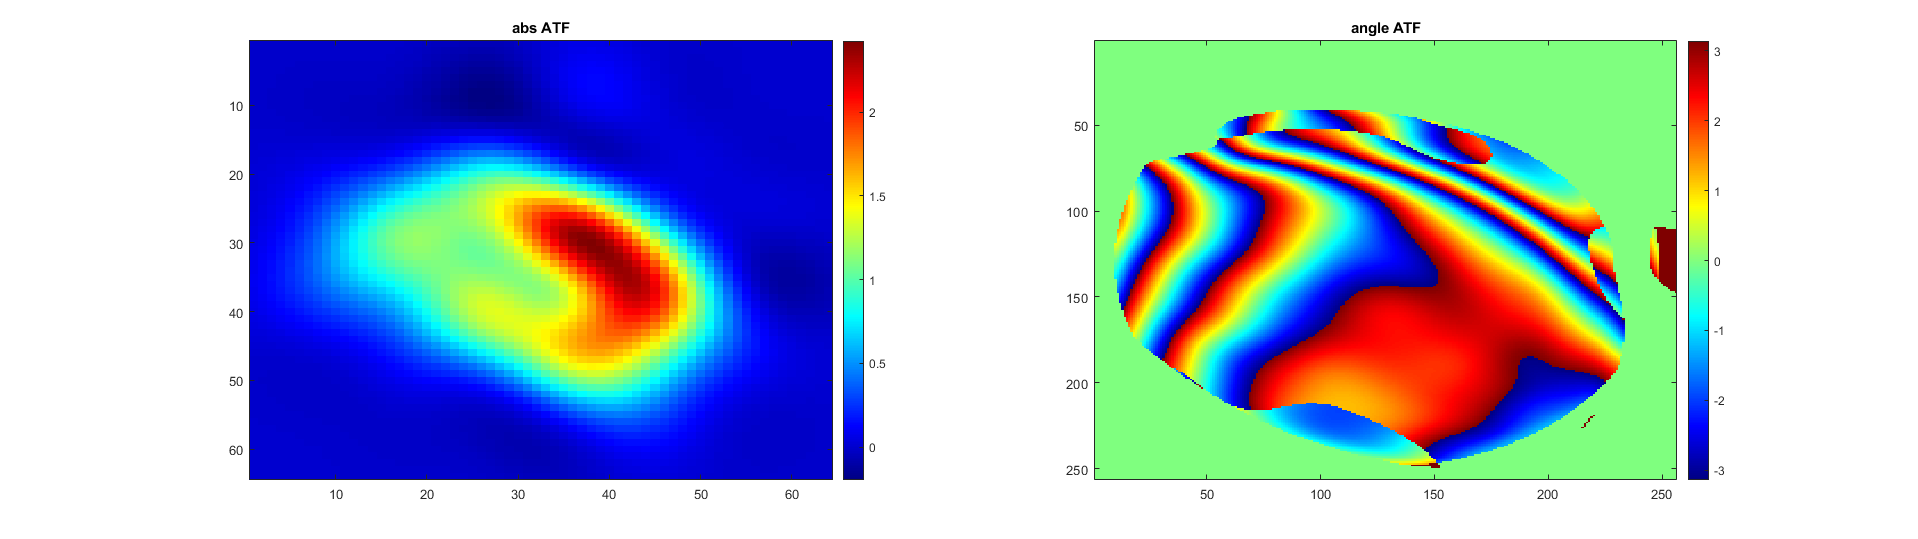

% imagesc(abs(ATF)); colormap(jet); colorbar();
E2_2 = zeros(64,64);
E2_2(33-16:33+20,33-16:33+20) = E(116-16:116+20,133-16:133+20);
ATF = FTS(E2_2);

[Dc2,aATF2_64,Phase] = DeconWienHZ(ATF,E,noise_area,H64,H256);

h12 = figure();
subplot(1,2,1);
imagesc(aATF2_64); colormap(jet); colorbar();
title('abs ATF')
subplot(1,2,2);    
imagesc(angle(Dc2)); colormap(jet); colorbar();
title('angle ATF')
set(h12,'Units','normalized','position',[0 0 1 .5])

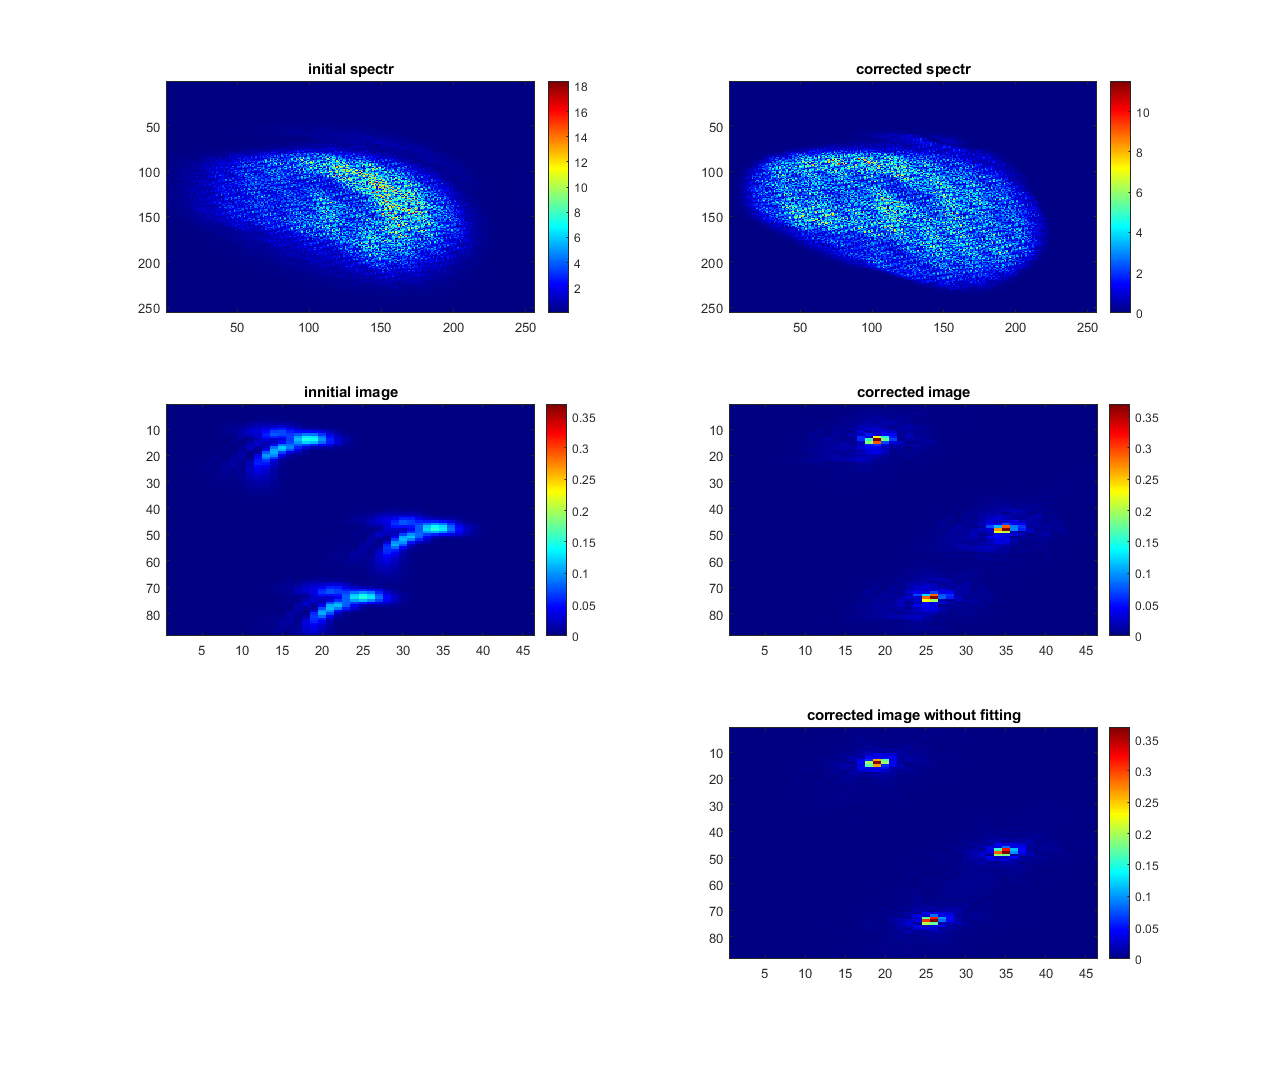

fE = FTS(E);
fE2_1 = fE.*Dc2; 
E2cor_1 = iFTS(fE2_1);

E2cor_1 = E2cor_1.*normf(E2cor_1,E); 

h14 = figure();
subplot(3,2,1);
imagesc(abs(fE)); colormap(jet); colorbar();
title('initial spectr')
subplot(3,2,2);    
imagesc(abs(fE2_1)); colormap(jet); colorbar();
title('corrected spectr')
subplot(3,2,3);
imagesc(abs(E(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .37]);
title('innitial image')
subplot(3,2,4);    
imagesc(abs(E2cor_1(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .37]);
title('corrected image')
subplot(3,2,6);    
imagesc(abs(E2cor(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .37]);
title('corrected image without fitting')
set(h14,'Units','normalized','position',[0 0 2 3])

sh1 = shann_entropy(E2cor_1(103:190,115:160));
sh2 = shann_entropy(E2cor(103:190,115:160));
[sh1,sh2]

ans =     5.2488    4.8469


**High-order Zernike polynomials make it possible to obtain the same image quality without decomposition by polynomials.**